**HW #4**

In-class assignment:

## Problem 1

Create artificial 3-term mixture data with size n=1500 with

- 200 from N(5, 3^2)

- 800 from N(10, 1.5^2)

- 500 from N(15, 2^2)

(a) Give the kernel denisty estimate using normal kernel function.

(b) Generate N=1500 r.s. from the kernel density.

(c) Draw relative frequency histogram of data in a and the r.s. in b. Superimpose the mixture normal density. Compare the results with the r.s. from FM done in class.

% initializing
n = 1500;
nx = [200 800 500];
mus = [5 10 15];
sigs = [3 1.5 2];
data = zeros(n,1);

% generating rvs
data(1:nx(1)) = normrnd(mus(1), sigs(1), nx(1), 1);
data(nx(1)+1:nx(1)+nx(2)) = normrnd(mus(2), sigs(2), nx(2), 1);
data(nx(1)+nx(2)+1:n) = normrnd(mus(3), sigs(3), nx(3), 1);

% hist of rvs
%histogram(data, 20, 'normalization', 'probability')

## Exercise 9.19

Using the method for generating random variables from a finite mixture that was discussed in this chapter, develop and implement an algorithim for generating random variables based on a kernel density estimate (KDE). Use Geyser data. Compare KDE rs to FM rs.

% FM data generation:
% step 1: initialize a bunch of stuff

n = 500; % sample sz to gen

% FM rv generation
geyser = importdata("C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\geyser.mat");
geyser = geyser';

% setting mean, variance, mix params, iter, and tol
muin = [50 80]; piesin = [0.5 0.5]; varin = [1 1];
max_it = 100; tol = 0.001;

% step 2: use EM to find params that best describe data
[pies, mus, vars] = ...
    csfinmix(geyser, muin, varin, piesin, max_it, tol);

% step 3 generate the data using discussed method
fmData = zeros(n,1); % initialize
r = rand(1,n); % generate unif(0,1)

% counts instances where r falls into first mix
inst = length(find(r <= pies(1)));

% generates data using output from EM + instances
fmData(1:inst) = normrnd(mus(1), sqrt(vars(1)), inst, 1);
fmData(inst+1:n) = normrnd(mus(2), sqrt(vars(2)), n-inst, 1);


% KDE data generation:
kdeData = kdeDataGen(geyser, n)

kdeData =    44.6604   68.3398   70.7139   71.7118   64.3414   88.6101   47.1732   90.5631   78.0143   86.6439   55.2176   73.0720   75.8317   98.6380   60.6629   47.3575   51.3625   74.4485   40.7732   57.1946   49.2930   81.5229   82.3830   64.4243   61.2515   77.3244   63.8121   88.7382   64.7122   77.0181   53.0606   80.1480   78.0667   85.4205   79.0005   53.8362   95.0222   80.4151   83.3183   80.7256   81.0940   82.7180   77.8280   63.0346   90.0673   89.8478   54.5470   75.1901   93.2048   47.1996


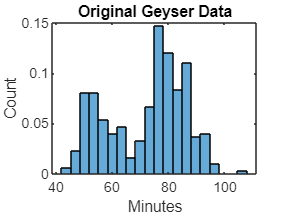



histogram(geyser,20, 'normalization', 'probability'); 
xlabel('Minutes')
ylabel('Count')
title('Original Geyser Data')

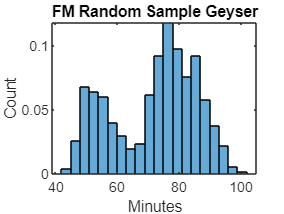


figure(2)
histogram(fmData,20, 'normalization', 'probability'); 
xlabel('Minutes')
ylabel('Count')
title('FM Random Sample Geyser')

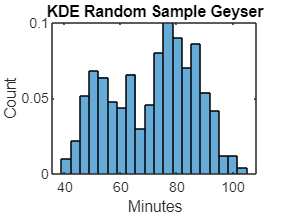


figure(3)
histogram(kdeData,20, 'Normalization','probability');
xlabel('Minutes')
ylabel('Count')
title('KDE Random Sample Geyser')

## Exercise 9.21

Apply some of the univariate density estimation techniques from this chapter to the forearm data. Generate rs from KDE. Draw relative frequency histogram of rs and compare with histogram of forearm data.

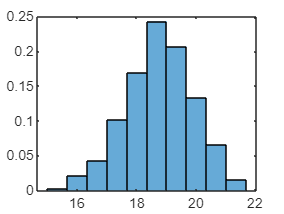

% initialize stuff

n = 1000; % sample to generate
forearm = importdata(...
    "C:\Users\casti\OneDrive\Desktop\School_Stuff\Masters_Stuff\STAT 572\CompStatsToolboxV2\forearm.mat");

kdeDat = kdeDataGen(forearm, n);
histogram(kdeDat, 10, "Normalization", "probability")

histogram(kdeDat, 10, "normalization", "probability")